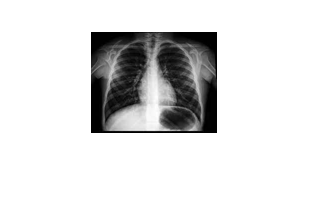

f=imread('radiograph1.jpg');
f=imresize(f,0.5);
f=double(f(:,:,1));
imshow(f,[])

edgex=[1,-1] %convolucion

edgex =      1    -1


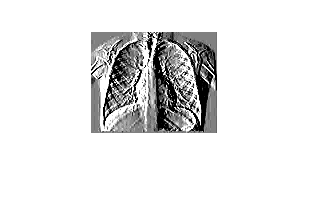

g1=conv2(f,edgex,'same'); 
imshow(g1,[-10,10]);

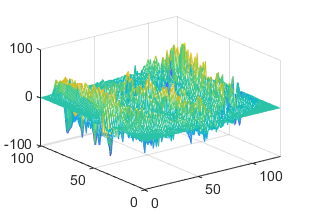

mesh(g1);

edgey=[-1 -2 -1;0,0,0;1,2,1]/8 %filtro de sobel

edgey =    -0.1250   -0.2500   -0.1250
         0         0         0
    0.1250    0.2500    0.1250


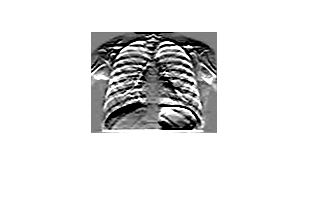

g2=conv2(f,edgey,'same'); %convolucion
imshow(g2,[-10,10])

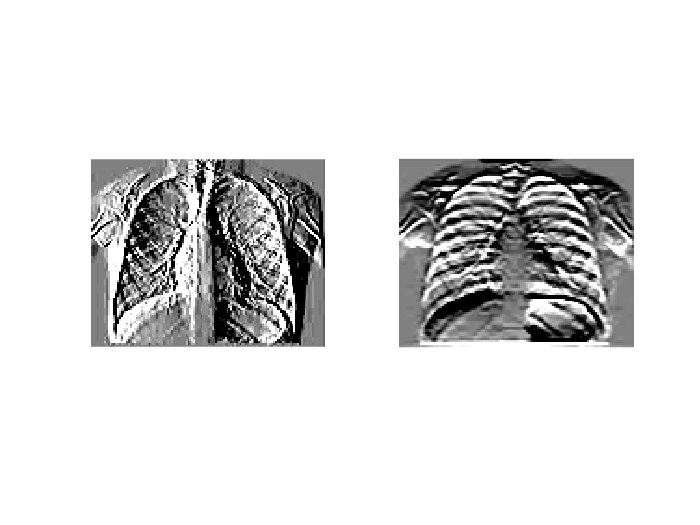

figure(2)
subplot(1,2,1)
imshow(g1,[-10,10]) %derivada en x
subplot(1,2,2)
imshow(g2,[-10,10]) %derivada en y

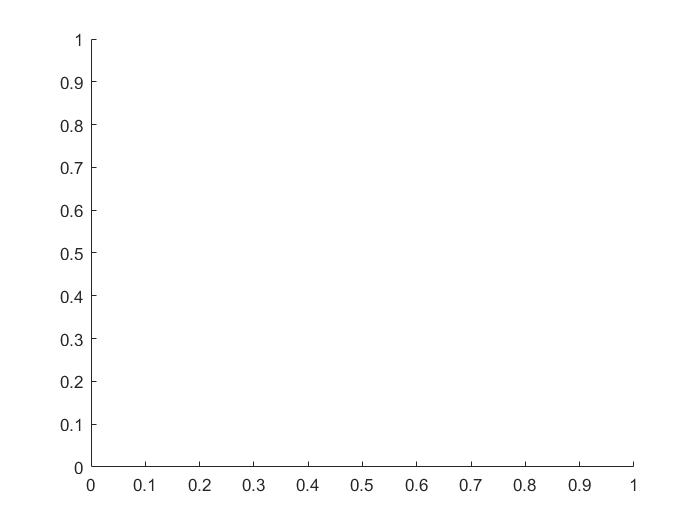

figure(3)
subplot(1,1,1)

edgex=[1,0,-1;2,0,-2;1,0,-1]/8

edgex =     0.1250         0   -0.1250
    0.2500         0   -0.2500
    0.1250         0   -0.1250


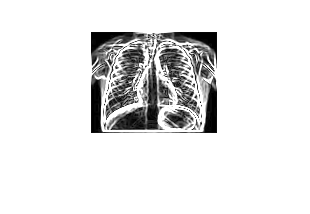

gx=conv2(f,edgex,'same');
gy=conv2(f,edgey,'same');
mag=sqrt(gx.^2+gy.^2); %magnitud del gradiente
imshow(mag,[0,20]);

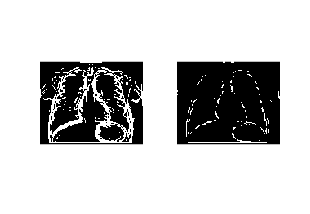

noisemask = [-1, 0 1]; %mascara derivativa
noiseimage = conv2(f,noisemask,'same'); %convolucion
noisevariance = mean2(noiseimage.^2);%varianza
noisestd = sqrt(noisevariance/2); %desviacion estandar
edgedetection1 = mag > noisestd;
edgedetection2 = mag > 2*noisestd;
subplot(1,2,1)
imshow(edgedetection1,[]);
subplot(1,2,2)
imshow(edgedetection2,[]);

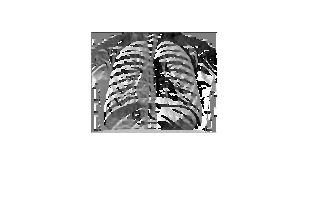

figure(4)
subplot(1,1,1)
angle=atan2(gy,gx); %angulo en radianes
imshow(angle,[]);

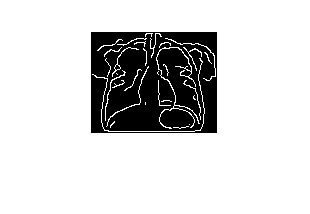

edgcany=edge(f,'Canny'); %deteccion por Canny
imshow(edgcany,[]);

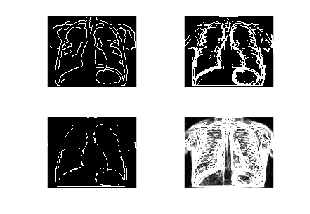

subplot (2,2,1)
imshow(edgcany,[])
subplot(2,2,2)
imshow(edgedetection1,[]);
subplot(2,2,3)
imshow(edgedetection2,[]);
subplot(2,2,4)
imshow(mag,[0,10])